## Problem Statement 1

What is the maximum value of the follwing equation on the range 0 < x < 5


$$y=-{\left(x-3\right)}^2 +10$$


What is the minimum of the function?

At what x value does the maximum y value occurs ?

Whats is y(20.7)?

clc, clearvars, close all

x = linspace (0,5);
y = (-(x-3).^2) + 10 

y =     1.0000    1.3005    1.5959    1.8861    2.1713    2.4514    2.7264    2.9962    3.2610    3.5207    3.7752    4.0247    4.2691    4.5083    4.7425    4.9715    5.1955    5.4143    5.6281    5.8368    6.0403    6.2388    6.4321    6.6203    6.8035    6.9815    7.1545    7.3223    7.4851    7.6427    7.7952    7.9427    8.0850    8.2222    8.3544    8.4814    8.6033    8.7201    8.8319    8.9385    9.0400    9.1364    9.2277    9.3139    9.3951    9.4711    9.5420    9.6078    9.6685    9.7241


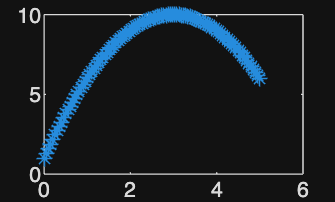


plot(x,y,'*')

max(y) % accuracy will realy on the data point you take

ans = 9.9996

min(y)

ans = 1


MaxVal = max(y) % help max

MaxVal = 9.9996

[MaxVal,I] = max(y) % find index

MaxVal = 9.9996

I = 60

x_maxval = x(I) % find value of x at that index

x_maxval = 2.9798

We need to learn about anonymous functionf for solving y(x)

y = @(x) (-(x-3).^2) + 10; % anonymous function @(x) before func
y(20.7)

ans = -303.2900

## Problem Statement 2

Plot the equation from x = -10 to 10

 
$$y=-{\left(x-3\right)}^2 +10\;$$


How dies the curve change if 15 is added instead of 10?

How does the curve changes if (x-5) is in parenthesis?

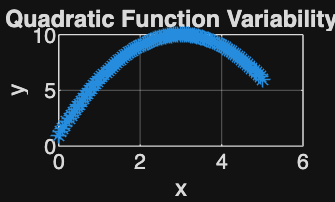

x = linspace (0,5);
y = (-(x-3).^2) + 10; 
y1 = (-(x-3).^2) + 15; 
y2 = (-(x-5).^2) + 10; 

figure(1)
plot(x,y,'*') % help plot or doc plot
xlabel('x'),ylabel('y'),title('Quadratic Function Variability 1')
grid on

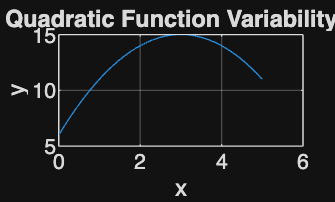



figure(2)
plot(x,y1)
xlabel('x'),ylabel('y'),title('Quadratic Function Variability 2')
grid on 

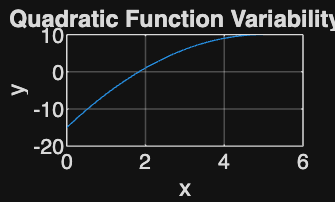


figure(3)
plot(x,y2)
xlabel('x'),ylabel('y'),title('Quadratic Function Variability 3')
grid on

Mergeplot | Subplots in Matlab

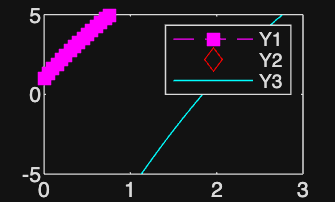

figure(4)
%subplot(2,3,1)
xlabel('x'),ylabel('y'),title('Quadratic Function Variability 1')
grid on 

plot(x,y,'--ms','MarkerFaceColor','m','MarkerSize',6)
hold on 
%subplot(2,3,2)
plot(x,y1,'rd') % r for red and d for diamonds
hold on 
%subplot(2,3,3)
plot(x,y2,'c') % cyan color

legend('Y1','Y2','Y3')
xlim([0 3]),ylim([-5 5])



% updated by matlab
ax = gca;
chart = ax.Children(1);
datatip(chart,4.949,9.997);

## Problem Statement 3

Based on the following equation, what percent of y values are greater than 0.8 for x = 0 to 10?


$$y=\sin \left(x\right)$$


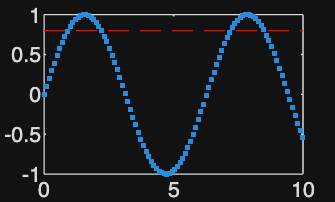

x = linspace(0,10,100);
y = sin(x);

figure(5)
plot(x,y,'.'), hold on, plot([0 10],[0.8 0.8],'--r')

Logical Operators (True, False, 0,1)

A = 11;
A < 10;
C = ones(10);
results = C>0;
sum(results);

55~=2; % not equal
10>5 & 11<0 % (Logic Orperators like Physics and Probab)

ans = logical
   0


10>5 | 11<0 % or operator

ans = logical
   1


Back to problem, for y > 0.8

y_greater = y > 0.8; %varies with the n 
FinalPercentage = sum(y_greater) / length(y)

FinalPercentage = 0.2500

% for matix : height() and width()

## Problem Statement 4

Generate 10 random values from 1 to 5. Count the number of 3's.

Display 'Wow!' if more than 20% of the random numbers are 3 

Do first two statement with a For Loop

Extent to 100 million random numbers - which method is faster?

clc, clearvars

% if statement
A = randi(5,1,10) %10 random in 1,5

A =      3     1     2     5     1     5     3     5     1     3


num3_if = sum(A==3)

num3_if = 3

if num3_if >=3 % change any value
 
   disp("Wow!")
end

Wow!


% -> %% makes section which run indepently like jupiter cell



% For Loop
num3_for =0; % initial before running we have 0 
for i = 1:length(A)
    if A(i) == 3
        num3_for = num3_for + 1;
    end
end

if num3_for >=3 % change any value
    disp("Wow!")
end   

Wow!


% for 100 million value
clc, clearvars
disp('------------')

------------


disp('Printing for 10 Million values')

Printing for 10 Million values


% if statement
A = randi(5,1,100000000); %100mil random in 1,5
num3_if = sum(A==3);
if num3_if >=0.2*length(A) % change any value
 
   disp("Wow!")
end
Time_if = toc

Time_if = 2.1019e+04

% -> %% makes section which run indepently like jupiter cell



% For Loop
num3_for =0; % initial before running we have 0 
for i = 1:length(A)
    if A(i) == 3
        num3_for = num3_for + 1;
    end
end

if num3_for >=0.2*length(A) % change any value
    disp("Wow!")
end   
Time_for = toc

Time_for = 2.1020e+04

While Loop

% While Loops
clc, clearvars

z = 100;

while z > 75 
    disp(sqrt(z)) % over and over cmd C for force quite
    z = z - 1 % to control
end

    10



z = 99

    9.9499



z = 98

    9.8995



z = 97

    9.8489



z = 96

    9.7980



z = 95

    9.7468



z = 94

    9.6954



z = 93

    9.6437



z = 92

    9.5917



z = 91

    9.5394



z = 90

    9.4868



z = 89

    9.4340



z = 88

    9.3808



z = 87

    9.3274



z = 86

    9.2736



z = 85

    9.2195



z = 84

    9.1652



z = 83

    9.1104



z = 82

    9.0554



z = 81

     9



z = 80

    8.9443



z = 79

    8.8882



z = 78

    8.8318



z = 77

    8.7750



z = 76

    8.7178



z = 75

disp('Loop Ended!')

Loop Ended!


% Running reduce_z_func
disp('Running reduced Z function')

Running reduced Z function


z = 100;
reduce_z_func(z)

z_final = 50

ans = 50

We did it!

Ping @ astrodingra@gmail.com for any queries 

~ Jashanpreet Singh Dingra